CA#1

Amir Hussain Birjandi 810198367

### 1.

## a.

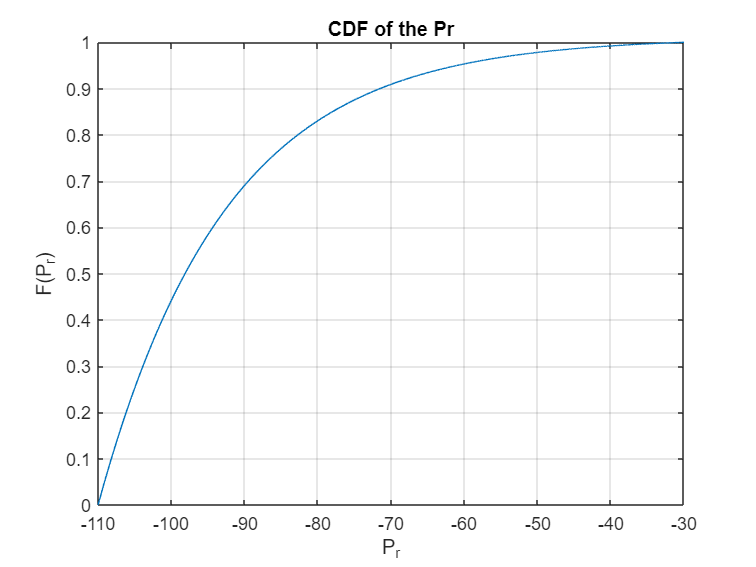

users = 1e5;
d0 = 10;
D = 1e3;
n=4;
P0 = 1e-6; % uwatt
N0 = -175; %dBm
B = 1e6;

d = d0:(D-d0)/users:D-(D-d0)/users;
Pr = (10*log10(P0)+30) - 10*n*log10(d/d0);
cdfplot(Pr);
xlabel('P_r');
ylabel('F(P_r)');
title('CDF of the Pr');

## b.

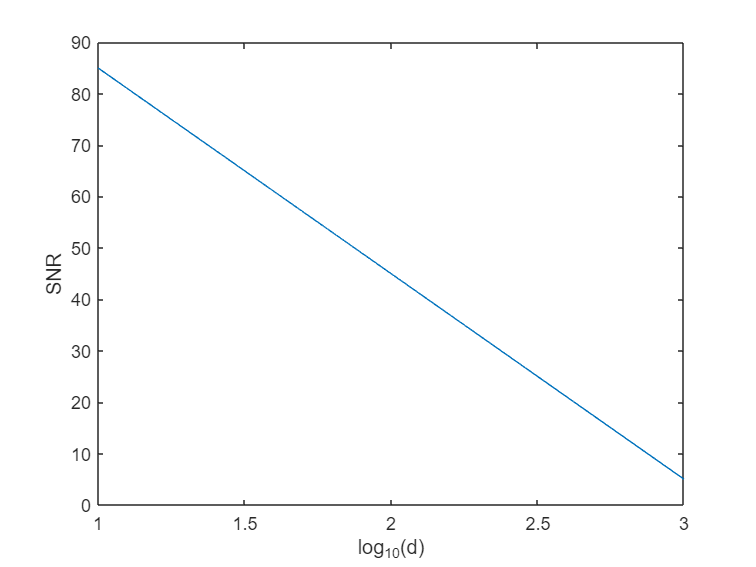

Pn = 10*log10(10^((N0-30)/10)*1e6)+30;
SNR = Pr - Pn;
plot(log10(d),SNR); 
xlabel('log_{10}(d)'); 
ylabel('SNR');

## Considering Shadowing Effect

## c.

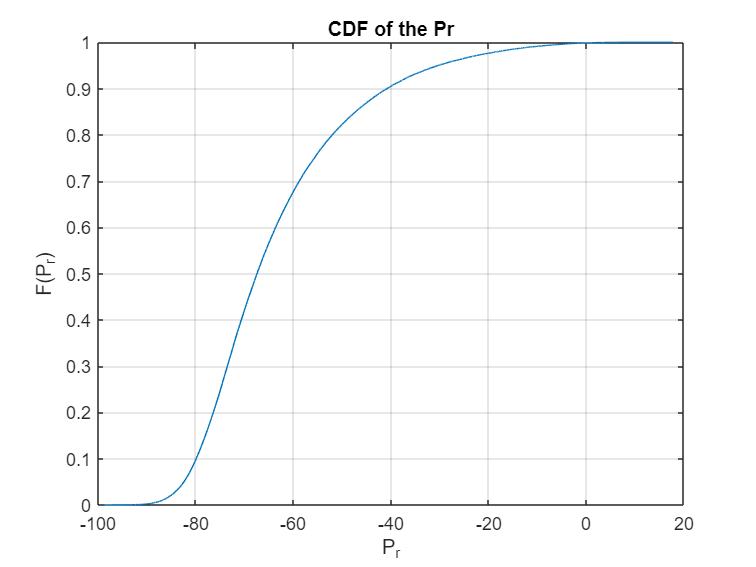

sigma = 5;
XdB = normrnd(0,sigma,1,100000);
Pr_with_shadowing = (10*log10(P0)+30) - 10*n*log10(d/d0) + XdB + 30;
cdfplot(Pr_with_shadowing);
xlabel('P_r');
ylabel('F(P_r)');
title('CDF of the Pr');

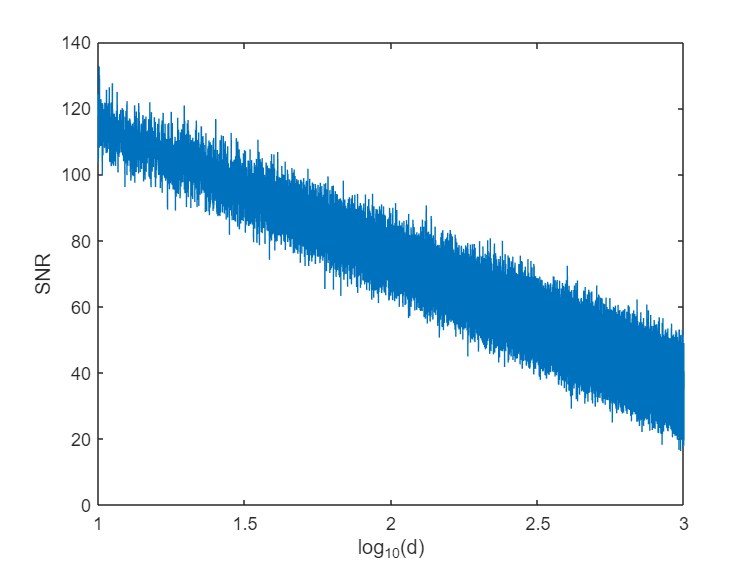

SNR_with_shadowing = Pr_with_shadowing - Pn;
plot(log10(d),SNR_with_shadowing); 
xlabel('log_{10}(d)'); 
ylabel('SNR');

## d.

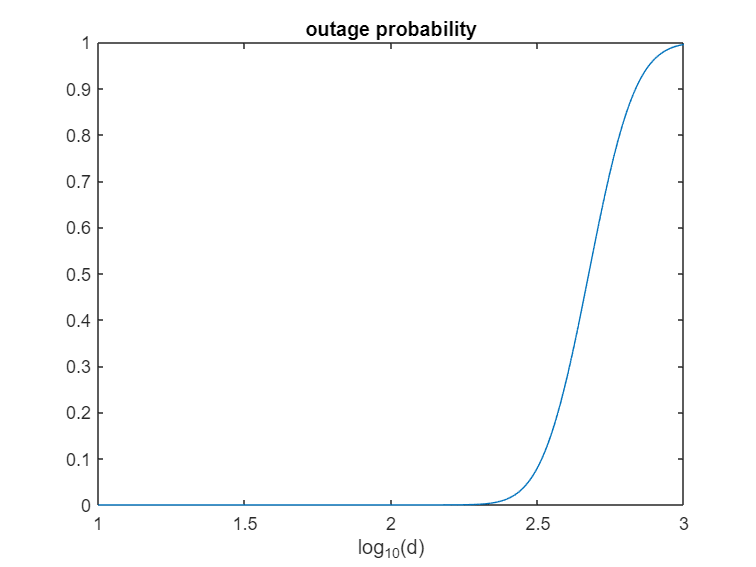

SNR_min = 18;
Pout = 1 - qfunc((SNR_min-SNR)/(sigma));
plot(log10(d),Pout);
xlabel('log_{10}(d)'); 
title('outage probability');

## 2.

### 1.

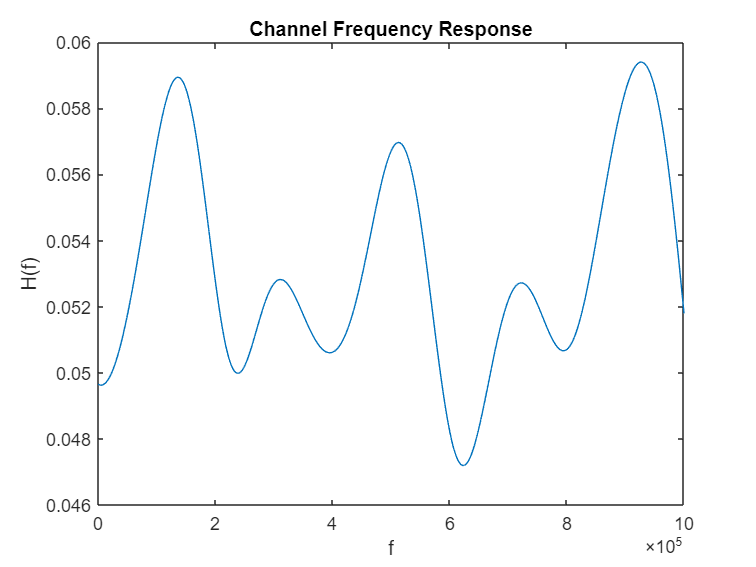

clusters = 15;
theta = unifrnd(0,pi/2,1,15);
v = 30;
fc = 3e9;
lamda = 3e8/fc;
tau = unifrnd(1e-6,10e-6,1,15);
f_duppler = v*cos(theta)/lamda;
duppler_phase = 2*pi*f_duppler.*tau;
alpha = raylrnd(sqrt(1/2.*1e-3.*(tau.*1e6).^(-4)));
phi = 2*pi*fc*tau - duppler_phase;

f=1:1:1e6;
f=repmat(f,clusters,1);

channel_fourier = sum(alpha.'.*exp(1j*phi').*exp(-2j*pi*tau.'.*f));
plot(f,abs(channel_fourier));
title('Channel Frequency Response')
xlabel('f')
ylabel('H(f)')

### 2.

reps = 1e5;
alpha =zeros(1,reps);

for i=1:reps
    tau = unifrnd(1e-6,10e-6,1,15);
    r = raylrnd(sqrt(1/2*1e-3.*(tau.*1e6).^(-4)));
    theta = unifrnd(0,pi/2,1,15);
    f_duppler = v*cos(theta)/lamda;
    duppler_phase = 2*pi*f_duppler.*tau;
    phi = 2*pi*fc*tau - duppler_phase;
    alpha(1,i) = sum(r.*exp(-1i*phi));
end

h2 = mean((abs(alpha)).^2);
fprintf('E{|h|^2} = %f',h2);

E{|h|^2} = 0.000558

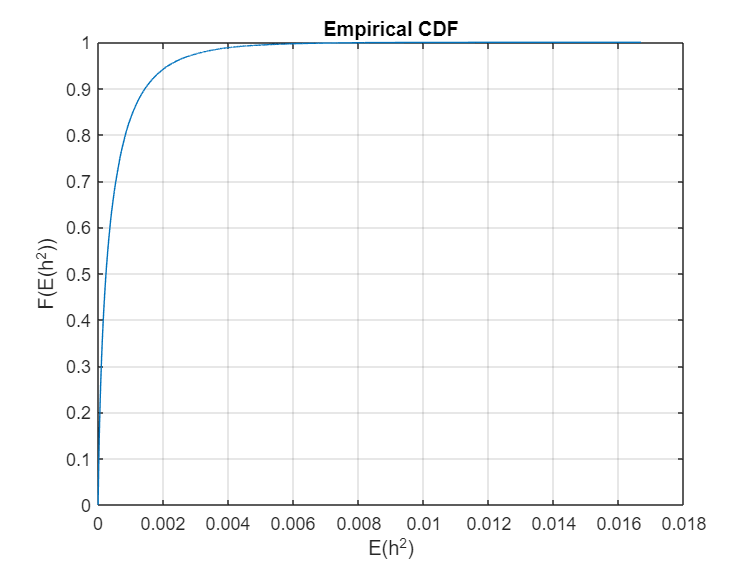

cdfplot((abs(alpha)).^2);
xlabel('E(h^2)')
ylabel('F(E(h^2))')

exponential random variable

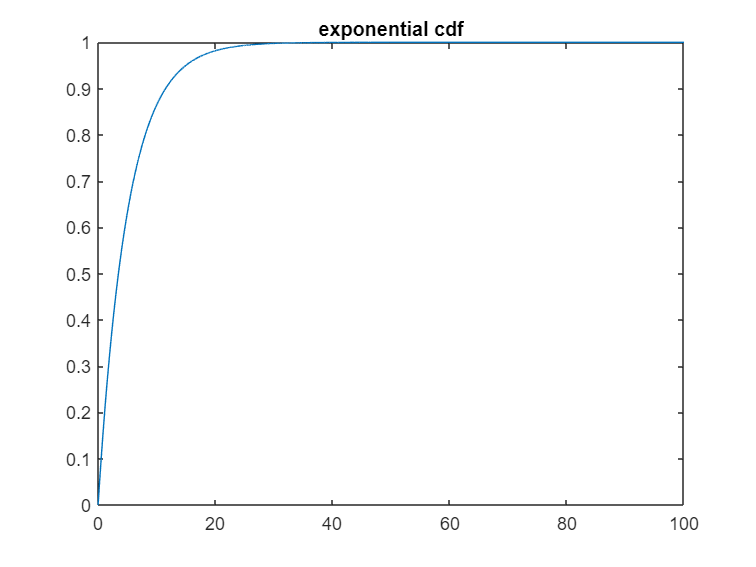

plot(0:0.01:100,expcdf(0:0.01:100,5))
title('exponential cdf')